# Problem 4 

## Author: Tomoki Koike

#### Using a 4096 FFT, plot 


$$f\left(t\right)\;=\;3+2\mathrm{cos}\left(2t\right)-4\mathrm{sin}\left(6t\right)\;\;\;\;\;L=\left\lbrack 0\;\;2\pi \right\rbrack$$


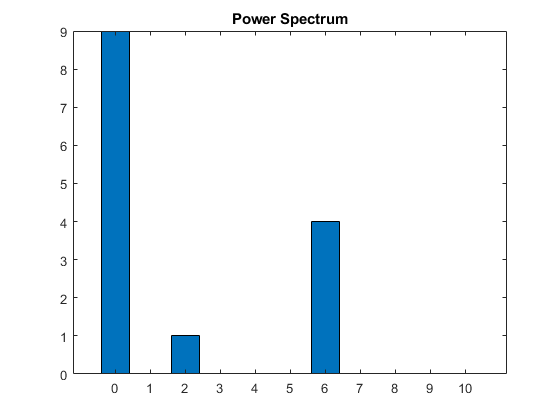

clear all 
close all 
clc

% Defining the span of time variable, t
t = (0:2^12-1)*2*pi/2^12;
% Defining the function subjected to FFT
f = 3 + 2*cos(2*t) - 4*sin(6*t);
% FFT 
a = ifft(f);

% Plot the power spectrum
figure(1)
bar((0:10), abs(a(1:11)).^2)
title('Power Spectrum')

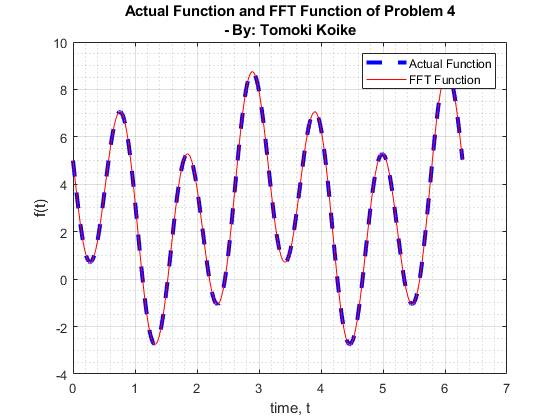


% From the power specturm the frequency we have to consider are a2=a(3) and
% a6=a(7)
% Partial Fourier Series Using Loop
p = a(1);
for k = 3:4:7
    p = p + 2*real(a(k)).*cos((k-1)*t) + 2*imag(a(k)).*sin((k-1)*t);
end

% PLotting 
figure(2);
plot(t, f, '--b', 'LineWidth', 3.0)
xlabel('time, t')
ylabel('f(t)')
title({'Actual Function and FFT Function of Problem 4', ['- By' ...
    ': Tomoki Koike']})
grid on
grid minor
box on
hold on 
plot(t, p, 'r')
hold off
legend('Actual Function', 'FFT Function')